# plot mean median profiles

new_env(7);
load('/home/zinger/workProjects/matlab_scripts/cluster/mat_files/cl7_mean_median_profs.mat')

r200=get_rvir(200);
r500=get_rvir(500);


## plot density profiles

cm=brewermap(6,'Set1');

figure

for i=1:4
h(1)=loglog(emsStruct(i).rb,emsStruct(i).rhoMean,'Color',cm(1,:),'DisplayName','Mean');
hold on 
loglog(emsStruct(i).rb,emsStruct(i).rhoMean-0.5.*emsStruct(i).rhoStd,'--','Color',cm(1,:));
loglog(emsStruct(i).rb,emsStruct(i).rhoMean+0.5.*emsStruct(i).rhoStd,'--','Color',cm(1,:));
end

xlim([50 12e4])

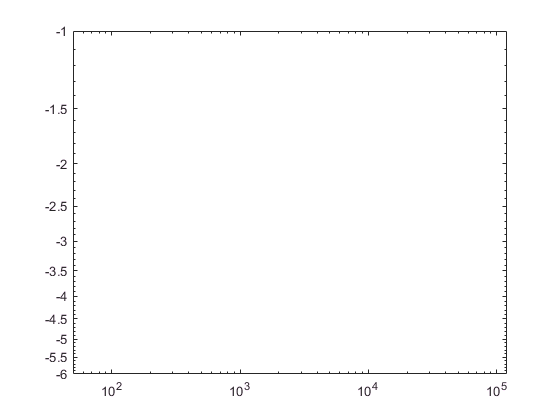

ylim([-6 -1])

%h(2)=loglog(emsStruct.rb,emsStruct(1).rhoMed,'DisplayName','Med');

